# Time lapsed tSNE plots of syllables

### Choose settings

% Query for syllables to be retrieved
birdname = 'br177yw112';
syls = ['bcdhjkrm'];
days = [62,661,88];

% set spectogram parameters
overlap_windowsize = [0.9 8];
numWindows = 50;
whichWindows = ['1_to_' num2str(numWindows)];%['end-' num2str(numWindows) '_to_end'];
spect_params = struct("overlap_windowsize",overlap_windowsize,"numWindows",numWindows,"whichWindows",whichWindows);

### Compile the spectrogram matrices for syllable trials

% directory where compiled data will be saved
savedir = "C:\Users\LPASCU2\OneDrive - Emory University\MATLAB_CODE\ephys-songbird\data\processed\tSNE_syllable_spects";
[spects_all,labels_all,days_all] = compileSylSpects(birdname,syls,days,savedir,spect_params);

day = 62

day = 661

day = 88

spects_all =     0.2805    0.2706    0.1838    0.1980    0.1993    0.1993    0.1004    0.2531    0.3715    0.4542    0.4115    0.4464    0.3917    0.2540    0.2410    0.2224    0.2022    0.1062    0.1817    0.0413    0.1014    0.0220    0.1190    0.0887    0.0126    0.0343    0.1349    0.1233    0.0836    0.0803    0.0972    0.0903    0.0858    0.0696    0.0252    0.0159    0.0073    0.0140    0.0193    0.0098    0.0138    0.0276    0.0308    0.0224    0.0213    0.0193    0.0155    0.0077    0.0098    0.0155
    0.1352    0.0427    0.0211    0.0127    0.1148    0.0660    0.0715    0.1358    0.2246    0.3864    0.4413    0.3333    0.2494    0.0679    0.5315    0.5097    0.0691    0.2560    0.1749    0.1079    0.1355    0.2062    0.2744    0.2977    0.2181    0.2036    0.1313    0.0882    0.1590    0.1394    0.2651    0.3799    0.3291    0.3446    0.4203    0.1613    0.2196    0.2149    0.3066    0.2839    0.1565    0.0638    0.0437    0.1014    0.0704    0.0233    0.0704    0.0494    0.

labels_all = 'cdbcddbcddbcdbcdbcdbcddbcdbcddbcdbcdbcbcdbcdbcdbcddbcddbbcdddbcdbcdbcddbcbcdbcdddbcdbcdbcddbbcdcddbcddbcbcdbcdbcdbcdbcbcddbcdbcbdddbbcdbcddddbcdbcddbcdbcdbccbcdbcddbcddbcddbbbcdbcdddbcddbcdbcdbcdbcdbcdbcddbcbcddbcbcmbcdbbcddbcdbcbcdbcbcddbcddbcddbcbcddbcbcddbcdbcbcddbcddbcdbcddbcdbcdbcddbcbcddbcbcddbcdddbcddddbcdbcddbcdbcddbcdbcbcbcddbcdbcdbcddbcbcbcbcbcbcddbcbcddbcbcdmbcddbcddbcdbcddbcbcddbcdbcdbcdbcdbcbcdmbcddbcbcddbcbcbcdbcdddbcdbcdbcddmbcdbcdbcddbcddbcdbcdbbcdbcbcdbcbcdbcdkddmbcddkcdmbcddbcdbckbcdbcdbbcdddbbcdkrkrkrmbcddbcdmbcdbcdkrdbckrmdcdbcdbckrkrkrbcdbcddkrkrbcdbckrkrkrmmbcdbcddbbcdbcdddbcdddbcdbckrkrkrkrkrdbcddbmbcddmbcdbcddbcdmbcdcddbcddkrkrkrkrdbcdmbcdbbcdbcdbcddddbcddbcddbcddkrkrkrkrkbcddbcdkrkrkrkrbcddbcdddddbcdbcddbcdbckrkrbcdbcddddbcddbcdbcdddbdbcdbckrkrkmmmmbcdbcddddkrmmmbcdkrkrkmbcdbcdbcdbcdbbddkrkrkrkmmmbbcdbcddbckrkrkrkrbcdddbcdbcddbcdbcdkrkrkrkdbcdbcddbckrkrbcdbcdbcddbcdbcdkrkrkrkrkbcdbcddbcdbcdddkbcdbcdbcdbbcdbcdbcdbcdbckrkrkbcdbckrdbckmbcdbcddjbcddbb

days_all =     62
    62
    62
    62
    62
    62
    62
    62
    62
    62


% Initialize feature matrix
spects_all = [];
labels_all = [];
days_all = [];
spect_uncut = {};
failedSyls ={};

% Concatenate spectrograms, syllable labels, and days
for d= 1:length(days)
    day = days(d)
    % change to folder containing files
    [~, ~,~,directory,~] = raster_params(birdname,day);
    cd(directory)

    spect_day = [];
    labels_day = [];
    try
    [spect_day, labels_day,spect_uncut_day] = getSpectMatrix(syls, spect_params);
    [spects_all] = [spects_all; spect_day];
    [labels_all] = [labels_all, labels_day];
    [days_all] = [days_all; repmat(day,size(spect_day,1),1)];
    spect_uncut{d} = spect_uncut_day;
    labels_by_day{d} = labels_day;

    catch exception
        message = ['failed for: ' num2str(day) ' -syl ' syls];
        failedSyls = [failedSyls; message];
        disp(message)
    end

    cd ..

end

day = 62

day = 661

day = 68

day = 73

day = 86

day = 88


% Replace values at indices 661 and 662 with 66
days_all(days_all == 661 | days_all == 662) = 66;
days(days == 661 | days == 662) = 66;

% Save output to processed data folder
cd("C:\Users\LPASCU2\OneDrive - Emory University\MATLAB_CODE\ephys-songbird\data\processed\tSNE_syllable_spects")
%Convert array of days to a string with underscores between them
daysString = strjoin(arrayfun(@(x) num2str(x), days, 'UniformOutput', false), '_');
dateGenerated = datetime();

% Concatenate the parts to create the filename
filename = strcat('spectrograms_syls_', syls, '_days', daysString, '_windows_', spect_params.whichWindows, '.mat');
% save
save(filename,"birdname","syls","days","spects_all","labels_by_day",...
    "labels_all","days_all","spect_uncut", "spect_params",...
    "dateGenerated")

% Load the existing .mat file
matFileName = filename;
matObj = matfile(matFileName, 'Writable', true);

% Create a new variable
newVariable = rand(3, 3);  % Replace this with your actual variable

% Append the new variable to the .mat file
matObj.newVariable = newVariable;


## Compile the matrix for feeding to tsne

% Step 3: Prepare Data for t-SNE
featureMatrix = spects_all;

% optional: normalize data?

% Step 4: Apply t-SNE with 3 dimensions
rng(42); % Set random seed for reproducibility
[tsneResult,loss] = tsne(featureMatrix, 'NumDimensions', 3);
disp(loss)

    2.3815



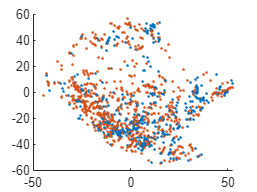

The logical indices in position 1 contain a true value outside of the array bounds.

% Step 5: Assign unique colors based labels
plotLabel = days_all; % assign which labels for coloring and grouping
    uniqueLabels = unique(plotLabel);
    numUniqueLabels = numel(uniqueLabels);
    colors = lines(numUniqueLabels); % You can use any colormap you prefer
    
    % Create a color map based on labels
    labelColors = zeros(length(plotLabel), 3);
    for i = 1:numUniqueLabels
        labelColors(plotLabel == uniqueLabels(i), :) = repmat(colors(i, :), [sum(plotLabel == uniqueLabels(i)), 1]);
    end
    
    % Assuming your character labels are stored in a character array
    charLabels = uniqueLabels; % Replace with your actual character labels
    
    % Convert character labels to double
    numericLabels = double(charLabels) - double('0') + 1;


% % Step 5b: Optional - assign unique colors based on second label
plotLabel2 = labels_all; % assign which labels for coloring and grouping
    uniqueLabels2 = unique(plotLabel2);
    numUniqueLabels2 = numel(uniqueLabels2);
    colors2 = lines(numUniqueLabels2); % You can use any colormap you prefer

    % Create a color map based on labels
    labelColors2 = zeros(length(plotLabel2), 3);
    for i = 1:numUniqueLabels2
        labelColors2(plotLabel2 == uniqueLabels2(i), :) = repmat(colors2(i, :), [sum(plotLabel2 == uniqueLabels2(i)), 1]);
    end

    % Assuming your character labels are stored in a character array
    charLabels2 = uniqueLabels2; % Replace with your actual character labels

    % Convert character labels to double
    numericLabels2 = double(charLabels2) - double('0') + 1;

% Create 3D scatter plot
figure;
hold on;
    for i = 1:numUniqueLabels
        idx = plotLabel == uniqueLabels(i);
        scatter3(tsneResult(idx, 1), tsneResult(idx, 2), tsneResult(idx, 3), 3, labelColors(idx, :), 'filled');
        
        % Label each cluster with the associated character
        centroid = mean(tsneResult(idx, :), 1);

        % Get the color of the cluster for text color
        text_color = labelColors(find(idx, 1), :);
        % text(centroid(1), centroid(2), centroid(3), uniqueLabels(i), 'FontSize', 30, 'FontWeight', 'bold', 'Color', text_color);
    end


for i = 1:numUniqueLabels2
    idx = plotLabel2 == uniqueLabels2(i);
    % scatter3(tsneResult(idx, 1), tsneResult(idx, 2), tsneResult(idx, 3), 3, labelColors2(idx, :), 'filled');
    
    % Label each cluster with the associated character
    centroid2 = mean(tsneResult(idx, :), 1);
    text(centroid2(1), centroid2(2), centroid2(3), uniqueLabels2(i), 'FontSize', 30, 'FontWeight', 'bold');
end
hold off;

title(['br177yw112 - syllables: ' syls ' by day']);
% subtitle('settings: exact, euclidean')
xlabel('t-SNE1');
ylabel('t-SNE2');
zlabel('t-SNE3');
% legend('D62','D66','D68','D73','D86','D88', "Location","southeast")

% Load your matrix (replace 'your_file.mat' with your actual file)
filename = 'spectrograms_syls_bcdhjkrm_days62_661_68_73_86_88_windows_1_to_50.mat'

filename = 'spectrograms_syls_bcdhjkrm_days62_661_68_73_86_88_windows_1_to_50.mat'

load(filename);

% Create the tSNE on the whole dataset
tsneResultAll = tsne(spects_all,'NumDimensions',3);

% Define parameters
bin_width = 2000;
bin_step = 300;

% Create a VideoWriter object
video_filename = [filename(1:end-4) '_MOVIE.avi']

video_filename = 'spectrograms_syls_bcdhjkrm_days62_661_68_73_86_88_windows_1_to_50_MOVIE.avi'

video_writer = VideoWriter(video_filename);
video_writer.FrameRate = 10;
open(video_writer);

figure;

for start_row = 1:bin_step:(size(spects_all, 1) - bin_width + 1)
    end_row = start_row + bin_width - 1;
    
    % Extract the current window and labels
    tsneResult = tsneResultAll(start_row:end_row, :);
    plotLabel = labels_all(start_row:end_row);
    uniqueLabels = unique(plotLabel);
    numUniqueLabels = numel(uniqueLabels);
    colors = lines(numUniqueLabels); % You can use any colormap you prefer
    
    % Create a color map based on labels
    labelColors = zeros(length(plotLabel), 3);
    for i = 1:numUniqueLabels
        labelColors(plotLabel == uniqueLabels(i), :) = repmat(colors(i, :), [sum(plotLabel == uniqueLabels(i)), 1]);
    end

    % Create 3D scatter plot
    hold on;

    % Incorporate your existing code for the first set of labels and colors
    for i = 1:numUniqueLabels
        idx = plotLabel == uniqueLabels(i);
        scatter3(tsneResult(idx, 1), tsneResult(idx, 2), tsneResult(idx, 3), 3, labelColors(idx, :), 'filled');
        
        % Label each cluster with the associated character
        centroid = mean(tsneResult(idx, :), 1);

        % Get the color of the cluster for text color
        text_color = labelColors(find(idx, 1), :);
        text(centroid(1), centroid(2), centroid(3), uniqueLabels(i), 'FontSize', 30, 'FontWeight', 'bold', 'Color', text_color);
    end

    % % Incorporate your existing code for the second set of labels and colors
    % for i = 1:numUniqueLabels2
    %     idx = plotLabel2 == uniqueLabels2(i);
    %     scatter3(tsneResult(idx, 1), tsneResult(idx, 2), tsneResult(idx, 3), 3, labelColors2(idx, :), 'filled');
    % 
    %     % Label each cluster with the associated character
    %     centroid2 = mean(tsneResult(idx, :), 1);
    %     text(centroid2(1), centroid2(2), centroid2(3), uniqueLabels2(i), 'FontSize', 30, 'FontWeight', 'bold');
    % end

    hold off;

    % Additional formatting if needed
    title(['br177yw112 - syllables: ' syls ' by day']);
    xlabel('t-SNE1');
    ylabel('t-SNE2');
    zlabel('t-SNE3');
    view(3)
    % legend('D62', 'D66', 'D68', 'D73', 'D86', 'D88', "Location", "southeast");

    % Pause for a short duration to create the animation effect
    pause(0.1);

    % Capture the current frame for the movie
    frame = getframe(gcf);
    writeVideo(video_writer, frame);

    % Clear the current figure for the next iteration
    clf;
end

% Close the video writer
close(video_writer);

% Create the tSNE on the whole dataset
tsneResultAll = tsne(spects_all,'NumDimensions',3,'Algorithm','exact');

% Define parameters
bin_width = 2000;
bin_step = 500;

figure;

for start_row = 1:bin_step:(size(spects_all, 1) - bin_width + 1)
    end_row = start_row + bin_width - 1;
    
    % Extract the current window and labels
    tsneResult = tsneResultAll(start_row:end_row, :);
    plotLabel = labels_all(start_row:end_row);
    uniqueLabels = unique(plotLabel);
    numUniqueLabels = numel(uniqueLabels);
    colors = lines(numUniqueLabels); % You can use any colormap you prefer
    
    % Create a color map based on labels
    labelColors = zeros(length(plotLabel), 3);
    for i = 1:numUniqueLabels
        labelColors(plotLabel == uniqueLabels(i), :) = repmat(colors(i, :), [sum(plotLabel == uniqueLabels(i)), 1]);
    end

    % Create 3D scatter plot
    hold on;

    % Incorporate your existing code for the first set of labels and colors
    for i = 1:numUniqueLabels
        idx = plotLabel == uniqueLabels(i);
        scatter3(tsneResult(idx, 1), tsneResult(idx, 2), tsneResult(idx, 3), 3, labelColors(idx, :), 'filled');
        
        % Label each cluster with the associated character
        centroid = mean(tsneResult(idx, :), 1);

        % Get the color of the cluster for text color
        text_color = labelColors(find(idx, 1), :);
        text(centroid(1), centroid(2), centroid(3), uniqueLabels(i), 'FontSize', 30, 'FontWeight', 'bold', 'Color', text_color);
    end

    hold off;

    % Additional formatting if needed
    title(['br177yw112 - syllables: ' syls ' by day']);
    xlabel('t-SNE1');
    ylabel('t-SNE2');
    zlabel('t-SNE3');
    view(3)

    % Clear the current figure for the next iteration
    clf;
end